
A = linspace(-2*pi,2*pi,1000)

A =    -6.2832   -6.2706   -6.2580   -6.2454   -6.2329   -6.2203   -6.2077   -6.1951   -6.1826   -6.1700   -6.1574   -6.1448   -6.1322   -6.1197   -6.1071   -6.0945   -6.0819   -6.0693   -6.0568   -6.0442   -6.0316   -6.0190   -6.0064   -5.9939   -5.9813   -5.9687   -5.9561   -5.9436   -5.9310   -5.9184   -5.9058   -5.8932   -5.8807   -5.8681   -5.8555   -5.8429   -5.8303   -5.8178   -5.8052   -5.7926   -5.7800   -5.7674   -5.7549   -5.7423   -5.7297   -5.7171   -5.7046   -5.6920   -5.6794   -5.6668


B =    -6.2832   -6.2706   -6.2580   -6.2454   -6.2329   -6.2203   -6.2077   -6.1951   -6.1826   -6.1700   -6.1574   -6.1448   -6.1322   -6.1197   -6.1071   -6.0945   -6.0819   -6.0693   -6.0568   -6.0442   -6.0316   -6.0190   -6.0064   -5.9939   -5.9813   -5.9687   -5.9561   -5.9436   -5.9310   -5.9184   -5.9058   -5.8932   -5.8807   -5.8681   -5.8555   -5.8429   -5.8303   -5.8178   -5.8052   -5.7926   -5.7800   -5.7674   -5.7549   -5.7423   -5.7297   -5.7171   -5.7046   -5.6920   -5.6794   -5.6668


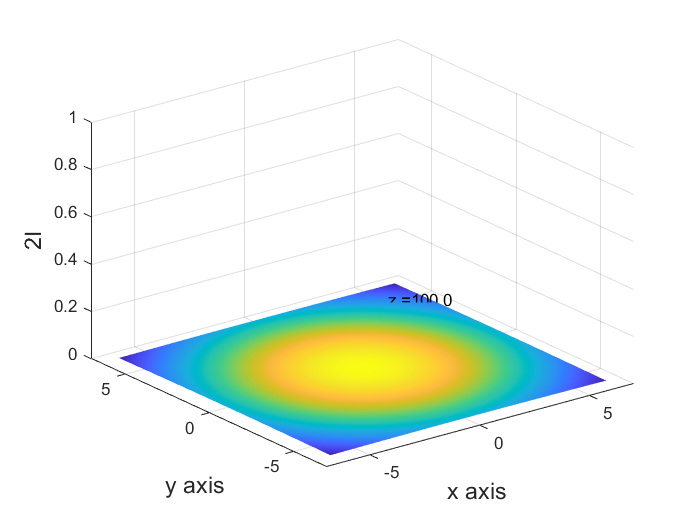

B = linspace(-2*pi,2*pi,1000)
[x,y] = meshgrid(A,B);
E0 = 1;
wFactor = 2;
lambda = 1;
w0 = wFactor*lambda;     
k = 2*pi/lambda;         
zR = pi*w0^2/lambda;  
myVideo = VideoWriter('myVideoFile1'); %open video file
myVideo.FrameRate = 10;  %can adjust this, 5 - 10 works well for me
open(myVideo)
for z = 0.1:0.1:100
    w = w0*sqrt(1+(z/zR).^2); 
    R = z.*(1+(zR./z).^2);    
    xi = atan(z./zR);
    
    E = E0*w0./w.*exp(-(x.^2 + y.^2)./w.^2).*exp(-1i*(k*z+k*(x.^2 + y.^2)./(2*R)-xi));
    I = abs(E) .^2;
    mesh(x,y,I,'Facecolor','interp','Edgecolor','none')
    xlabel('x axis','FontSize',14) 
    ylabel('y axis','FontSize',14) 
    zlabel('2I','FontSize',14)
    axis([-7 7 -7 7 0 1]);
    maxE = max(I,[],'all');
    s = sprintf('z =%0.1f',z);
    ht = text(5,5,maxE,s);
    pause(0.01);
    
    frame = getframe(gcf); %get frame
    writeVideo(myVideo, frame);
    
end

close(myVideo)
